# Video read in

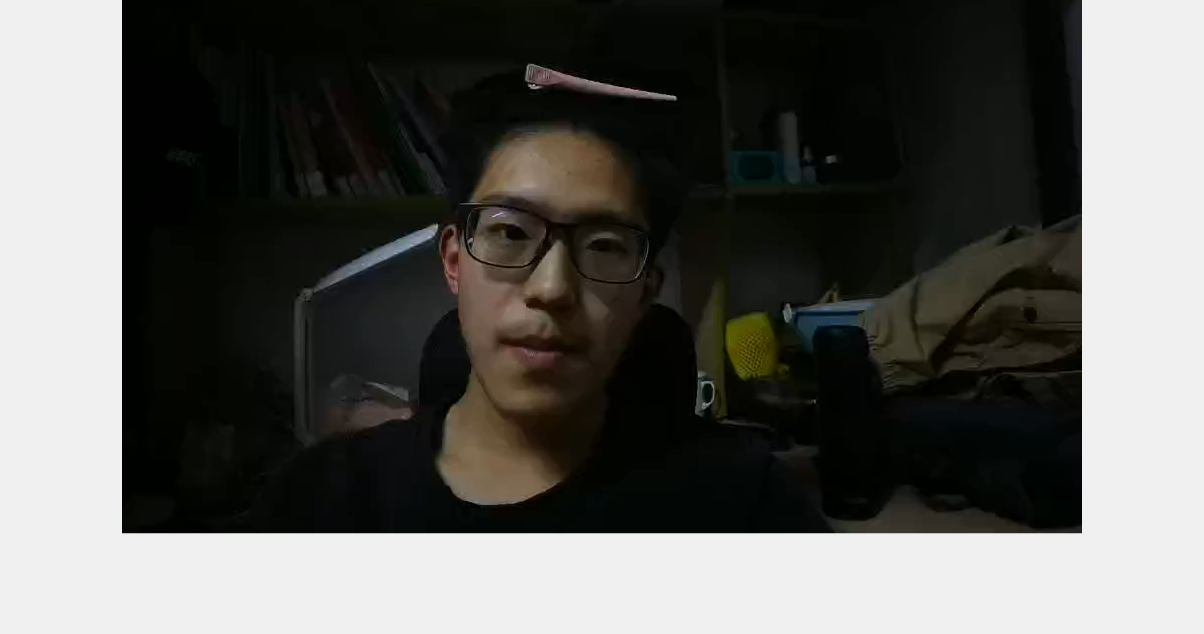

vid=VideoReader("/Users/lihaowei/semesters/git store/Comprehensive-practice/Heart rate detection/asset/videos/demo_1.mp4");
frames=read(vid,[1,inf]);
imshow(frames(:,:,:,1));
[x_bonder,y_bonder]=ginput(2);

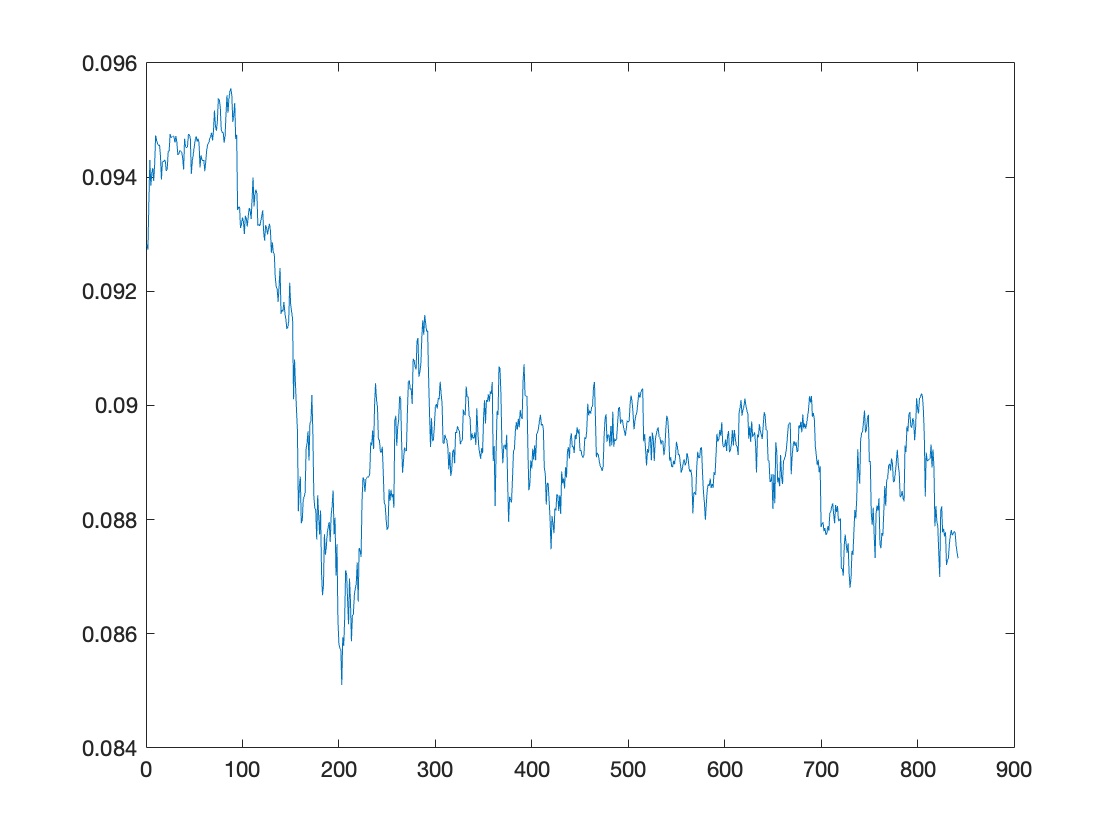

frames_seg=frames(y_bonder(1):y_bonder(2),x_bonder(1):x_bonder(2),:,:);
clear frames
h_avg=zeros([1,size(frames_seg,4)]);
threshold=0.1;
for i = 1:size(frames_seg,4)
    hsv_temp=rgb2hsv(frames_seg(:,:,:,i));
    h_temp=hsv_temp(:,:,1);
    tag=(h_temp<0.1);
    hvg=sum(sum(h_temp.*(tag)))/sum(sum(tag));
    if hvg>0.1
        keyboard;
    end
    h_avg(i)=hvg;
end
load filter.mat
%% high pass demo, filter length 30
filter_low=filter_hr.Numerator;
result=conv(h_avg,filter_low,"same");
result=result(31:end-31);
res_org=h_avg(31:end-31);
figure
plot(res_org)

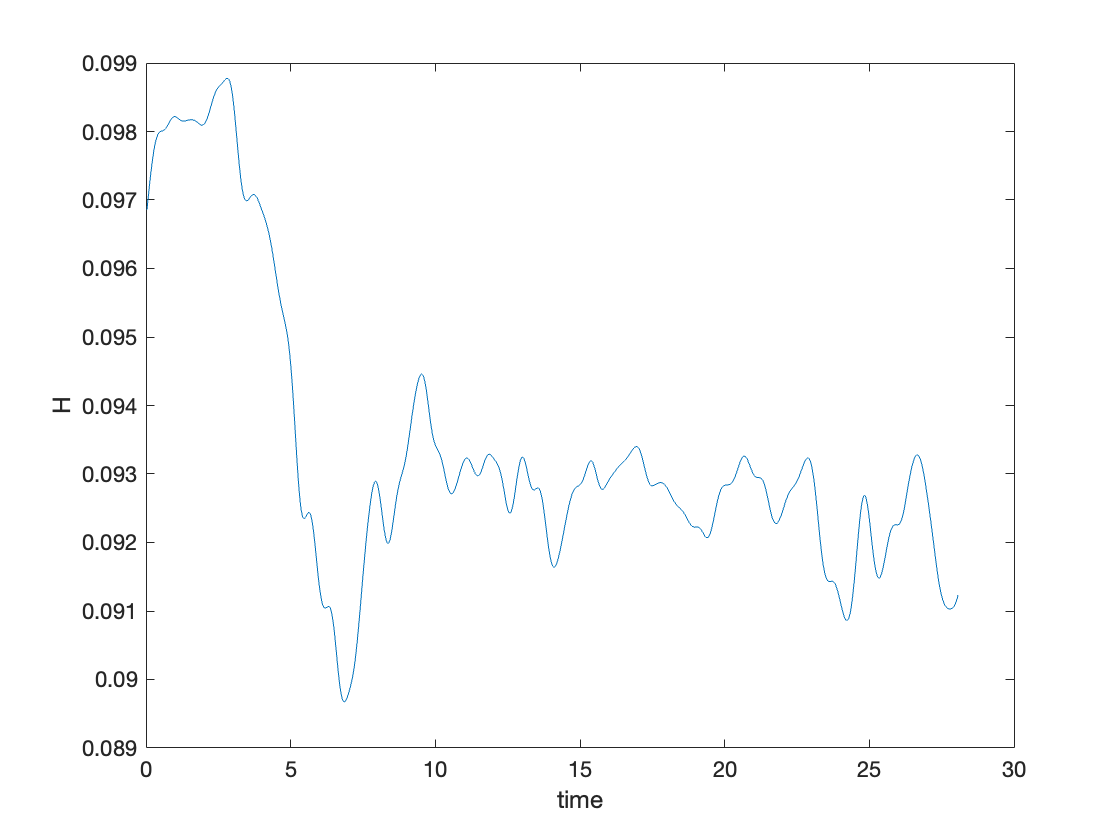

figure
plot([1:size(result,2)]/30,result)
xlabel('time');
ylabel('H');

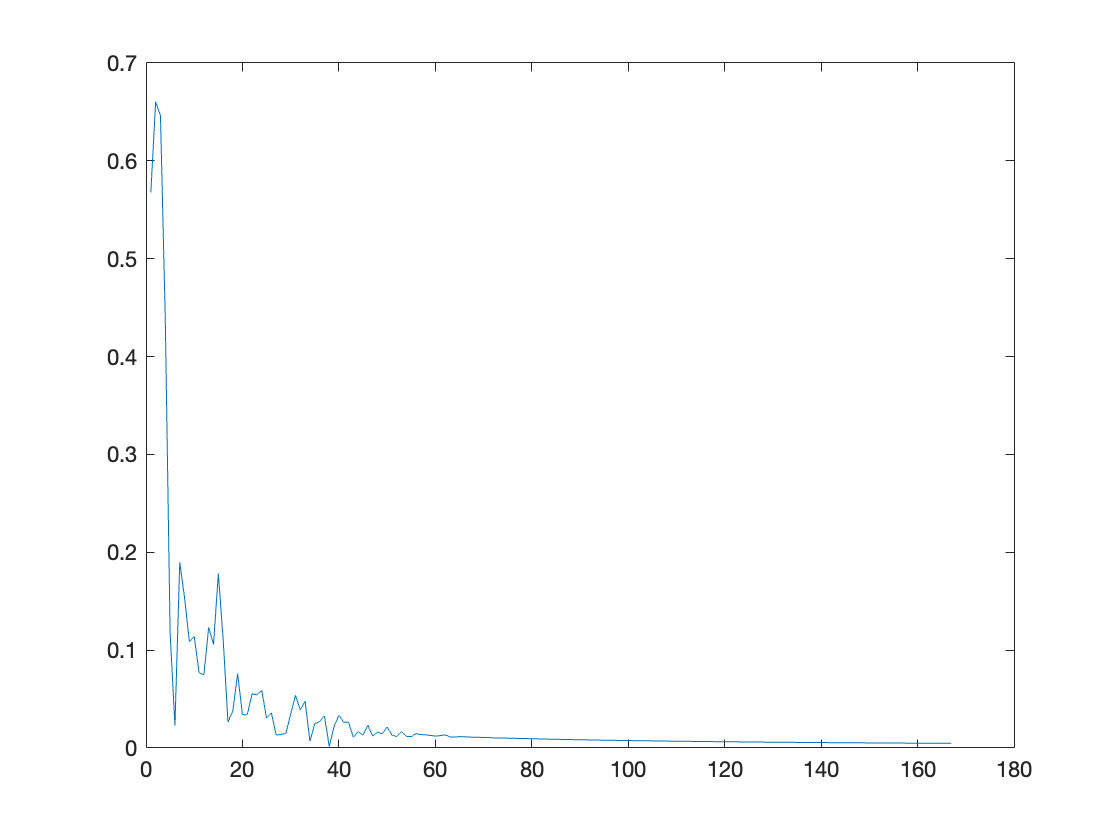

figure
spec=abs(fft(result));
plot(spec(2:end/5))

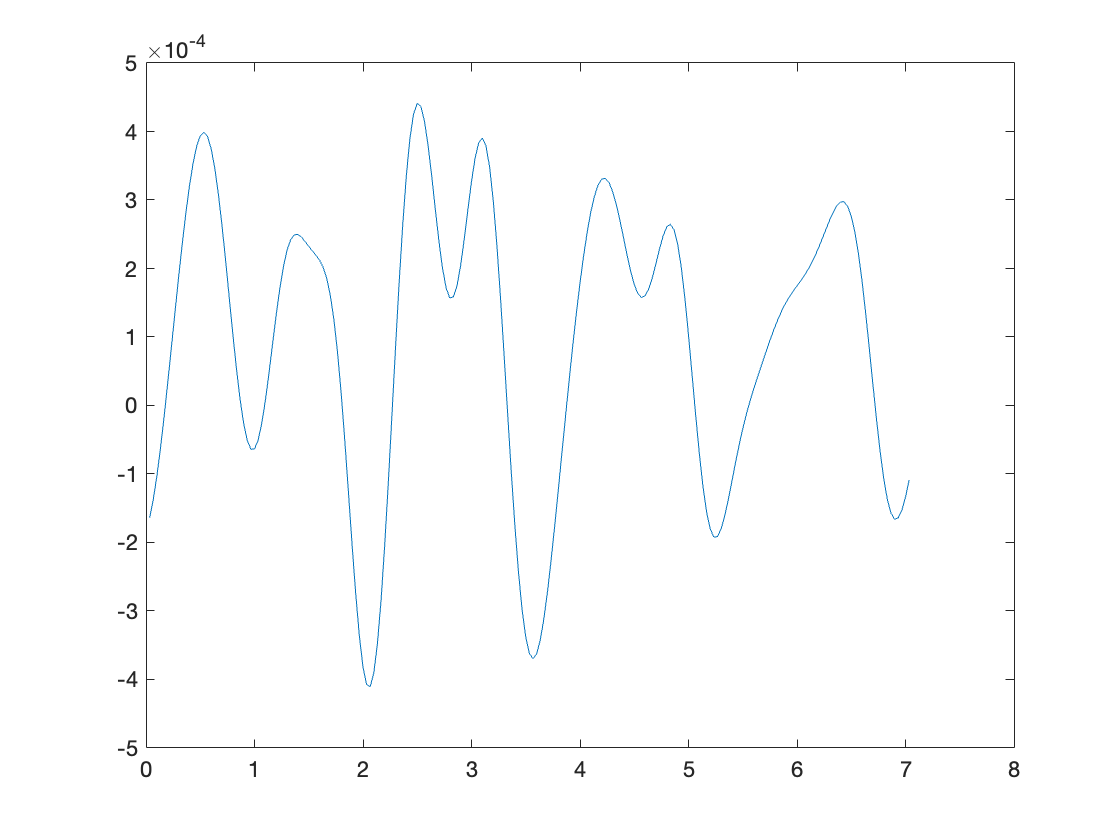


%%band pass demo, filter length 316
filter_bp_va=filter_bp.Numerator;
result_bp=conv(result,filter_bp_va,"same");
size_bp=size(filter_bp_va,2);
result_bp=result_bp(size_bp:end-size_bp);
figure;plot([1:size(result_bp,2)]/30,result_bp);

spec_bp=abs(fft(result_bp));
figure;plot(spec(2:end/5))